[**MIT License**](https://github.com/cdslaborg/paramonte#license)

[**ParaMonte: plain powerful parallel Monte Carlo library**](https://github.com/cdslaborg/paramonte)**.**

**Copyright (C) 2012-present, **[**The Computational Data Science Lab**](https://www.cdslab.org/#about)

[**https://github.com/cdslaborg/paramonte**](https://github.com/cdslaborg/paramonte)

# Making 2D kernel-density-estimate filled contour plots with the ParaMonte visualization tools

**NOTE**

If you are viewing an HTML version of this MATLAB live script on the web, you can download the corresponding MATLAB live script `visualization_contourf.mlx` file to this HTML page at,

[https://github.com/cdslaborg/paramontex/tree/master/MATLAB/mlx](https://github.com/cdslaborg/paramontex/tree/master/MATLAB/mlx)

Once you download the file, open it in MATLAB to view and interact with its contents, which is the same as what you see on this page. 

First, let's clean up the MATLAB environment and make sure the path to the ParaMonte library is in MATLAB's path list.

clc;
clear all;
close all;
format compact; format long;

%%%%%%%%%%%% IMPORTANT %%%%%%%%%%%%%
% Set the path to the ParaMonte library:
% Change the following path to the ParaMonte library root directory, 
% otherwise, make sure the path to the ParaMonte library is already added
% to MATLAB's path list.

pmlibRootDir = './';
addpath(genpath(pmlibRootDir),"-begin");
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% change MATLAB's working directory to the folder containing this script
% if MATLAB Live Scripts did not create a temporary folder, we would not
% have all of these problems!

try
    setwdFilePath = websave("setwd.m","https://github.com/cdslaborg/paramontex/raw/master/MATLAB/mlx/setwd.m");
    run(setwdFilePath); % This is a MATLAB script that you can download from the same GitHub location given in the above.
catch % alas, we will have to run the simulations in MATLAB Live Script's temporary folder
    filePath = mfilename('fullpath');
    [currentDir,fileName,fileExt] = fileparts(filePath); cd(currentDir);
    cd(fileparts(mfilename('fullpath'))); % Change working directory to source code directory.
end

## ParaMonte's default visualization tools

The ParaMonte library ships with several visualization tools that automate much of the MATLAB coding required to visualize the output of the simulations performed by the ParMonte library samplers. 

By replacing the input dataFrame to these tools and following the conventions of the ParaMonte library, one can also use these visualization tools for any dataset that may not have been generated by the ParaMonte library.

Consider the following Markov chain on the web in **compact** format generated by the **ParaDRAM** sampler of the ParaMonte library to sample a MultiVariate Normal distribution. Since this is a chain file as inidicated by its suffix `"_chain.txt"` We will read this file via the ParaDRAM sampler's `readChain()` method.

pm = paramonte();
pmpd = pm.ParaDRAM();
url = "https://github.com/cdslaborg/paramontex/raw/master/MATLAB/mlx/sampling_multivariate_normal_distribution_via_paradram/out/mvn_serial_process_1_chain.txt";
pmpd.readChain(url); % read the chain file from the web


ParaDRAM - WARNING: The ParaDRAM input simulation specification `pmpd.spec.outputDelimiter` is not set.
ParaDRAM - WARNING: This information is essential for successful reading of the requested chain file(s).
ParaDRAM - WARNING: Proceeding with the default assumption of comma-delimited chain file contents...

ParaDRAM - NOTE: 1 files detected matching the pattern: 
ParaDRAM - NOTE: "https://github.com/cdslaborg/paramontex/raw/master/MATLAB/mlx/sampling_multivariate_normal_distribution_via_paradram/out/mvn_serial_process_1_chain.txt"

ParaDRAM - NOTE: processing file: "D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\visualization\temp_20201004_035510_371.txt"
ParaDRAM - NOTE: reading the file contents... 
ParaDRAM - NOTE: done in 0.473680 seconds.
ParaDRAM - NOTE: ndim = 4, count = 50000

ParaDRAM - NOTE: computing the sample correlation matrix...

ParaDRAM - NOTE: creating the heatmap plot object from scratch...
ParaDRAM - NOTE: done in 0.314770 seconds.
ParaDRAM - NOTE: 

This method automatically generates a set of tools that can be used to visualize the contents of the compact chain file. Note that these visualization tools are not unique to this particular method of the ParaDRAM sampler or other ParaMonte samplers. For the sake of illustration however, we will create plots using the above dataset read via `readChain()` method of the ParaDRAM routine.

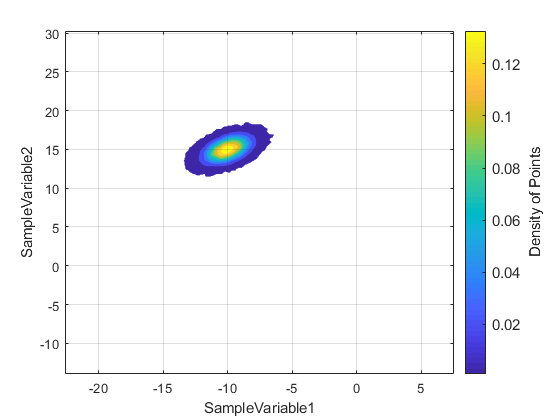

chain = pmpd.chainList{1};
chain.plot.contourf.make();

Be default, the visualization tools are loaded with a set of predefined settings. For example, ParaMonte visualizations are by default colored (unless mutiple variables are to be displayed). These however, can be readily changed. For example, to change the colormap,

chain.plot.contourf.colormap

ans = struct with fields:
    enabled: 1
     values: "parula"

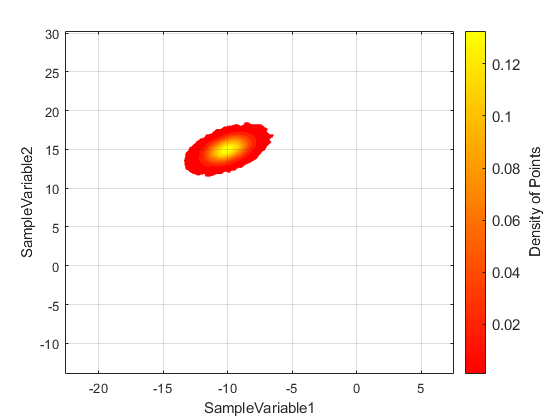

chain.plot.contourf.colormap.values = autumn;
chain.plot.contourf.make()

To draw the 3D kernel density estimate plots, the ParaMonte visualizer utilizes the` contourf()` function of MATLAB. One can pass pairs of (key,value) properties to this MATLAB function by defining those **keyword** properties in the `contourf` component of the plot object. There are a few properties defined already in this structure,

chain.plot.contourf.contourf.kws

ans = struct with fields:
           color: "none"
       lineStyle: "-"
       lineWidth: 0.500000000000000
        showText: "off"
    labelSpacing: 144

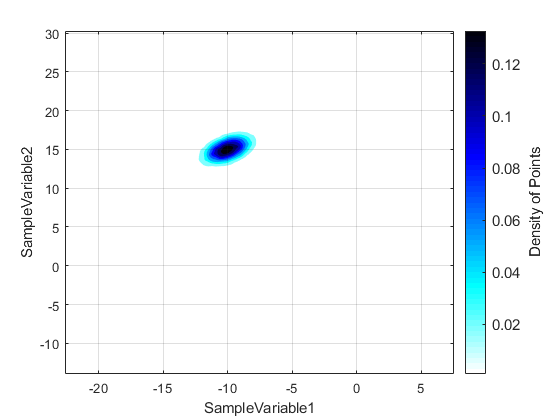

chain.plot.contourf.colormap.values = flipud(cold());
chain.plot.contourf.make();

To **reset** the properties of the plot object to the default settings, try, 

chain.plot.contourf.reset();

ParaDRAM - NOTE: resetting the properties of the contourf plot...


To reset the entire plot object including reading the data again from the input dataFrame, try, 

chain.plot.contourf.reset("hard");

ParaDRAM - NOTE: creating the contourf plot object from scratch...


Similarly, to change the properties of the **colorbar**, try, 

chain.plot.contourf.colorbar.kws

ans = struct with fields:
    fontSize: []

chain.plot.contourf.colorbar.kws.fontSize = 12;

To change properties that do not exist, simple add them to the `kws` component, for example, 

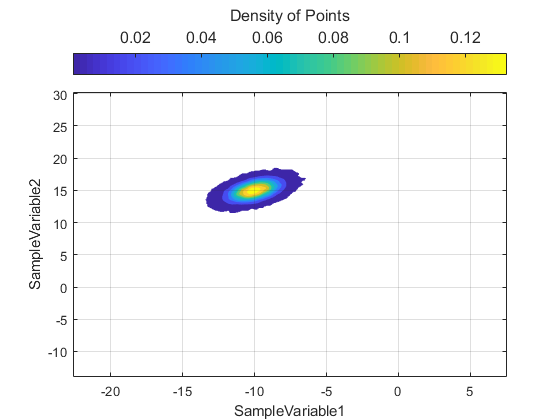

chain.plot.contourf.colorbar.kws.location = "northoutside";
chain.plot.contourf.make();

chain.plot.contourf.colorbar.kws

ans = struct with fields:
    fontSize: 12
    location: "northoutside"

Remember that a handle to all objects in the plot is also stored in the `currentFig` component of the object. Most of the properties of the figure, axes, and the plots can be also changed directly via these handles. For example, to change the colorbar label, we could try,

chain.plot.contourf.currentFig.colorbar.Label.String

ans = 'Density of Points'

chain.plot.contourf.reset();

ParaDRAM - NOTE: resetting the properties of the contourf plot...


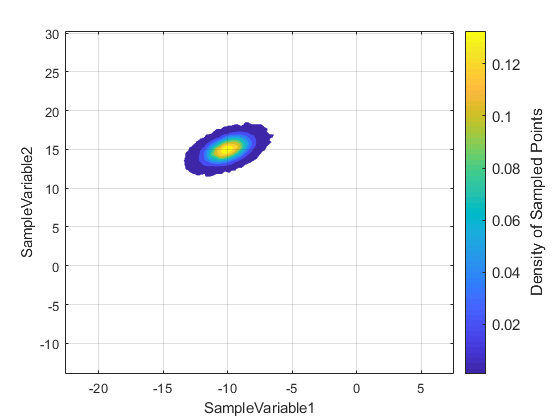

chain.plot.contourf.make();
chain.plot.contourf.currentFig.colorbar.Label.FontSize = 12;
chain.plot.contourf.currentFig.colorbar.Label.Interpreter = "tex"; % set the interpreter for the colorbar
chain.plot.contourf.currentFig.colorbar.Label.String = "Density of Sampled Points";

## Setting the resolution and the noise tolerance of the plot

If the resolution of the kernel density estimate in the plot is low, it can be increased by changing the value of the `gridSize` component of the plot object,

chain.plot.contourf.gridSize

ans =    512

This number must be a power of two (otherwise it will be made so, automatically). It represents the number of grid points along each axis of the plot and is used to set the resolution of the kernel density estimate. The higher this number, the higher the resolution of the estimate will be. However, larger values will be also computationally more expensive.

Similarly, if the resulting kernel density estimate appears to be noisy in the background, or perhaps there are some small density variations far from the high-density region that we may not want to display in the plot, we could remove it via,

chain.plot.contourf.noiseLevel

ans =      1.000000000000000e-03

Any density value below this threshold will be set to `nan`, such that it will not be displayed in the plot. 

## Choosing different columns of data to plot

By default, the column named the first two variables of the sampled space are shown in the plot. This can be readily changed to any paris of variables, like, 

chain.df.Properties.VariableNames

ans = 1×11 cell array
    {'ProcessID'}    {'DelayedRejectionStage'}    {'MeanAcceptanceRate'}    {'AdaptationMeasure'}    {'BurninLocation'}    {'SampleWeight'}    {'SampleLogFunc'}    {'SampleVariable1'}    {'SampleVariable2'}    {'SampleVariable3'}    {'SampleVariable4'}

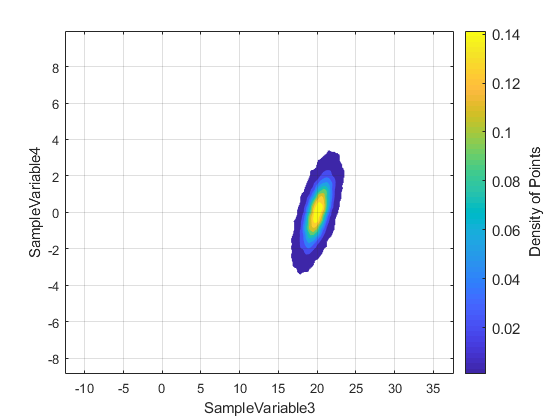

chain.plot.contourf.make( "xcolumns", "SampleVariable3", "ycolumns", 11);

Notice the possibility of use of both **column indices** and **column names** to point to a data column in the dataFrame.

## Unicolor plot

Turning the colormap off is very simple,

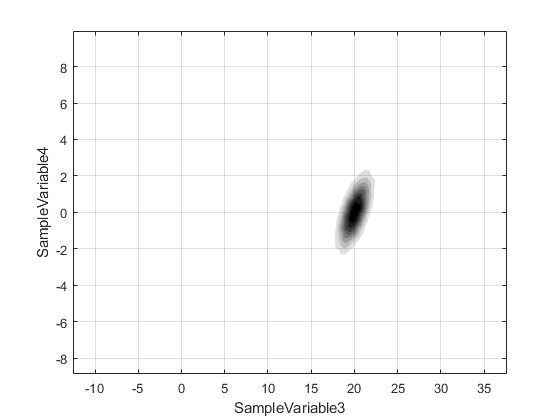

chain.plot.contourf.colormap.enabled = false; % make monocolor plot
chain.plot.contourf.make();

## Plotting specific rows of data

Selected rows of data can be also plotted, if not all data observations have to be included. For example, we can exclude the burnin episode as determined by the ParaMonte sampler, 

chain.plot.contourf.reset();

ParaDRAM - NOTE: resetting the properties of the contourf plot...


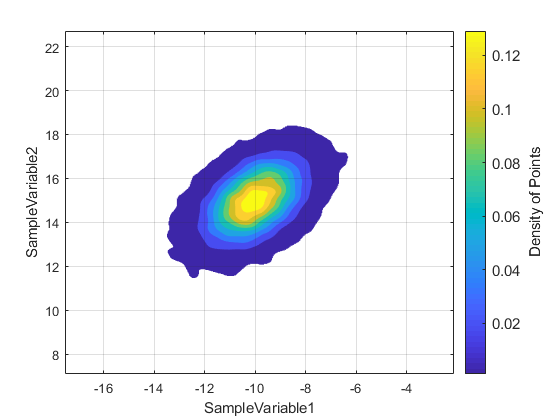

burnin = chain.df.BurninLocation(end); % get the inferred burning location at the end of the chain

chain.plot.contourf.rows = burnin:3:chain.count; % plot every one out of 10 data rows, starting from the burnin location to the end of the chain.
chain.plot.contourf.make();

## Adding targets to the plot

One can also **add target values** to the plots, use the `target()` component of the plot object. For example, to add the averages of the variables to the plot, one could try, 

chain.plot.contourf.reset("hard");

ParaDRAM - NOTE: creating the contourf plot object from scratch...


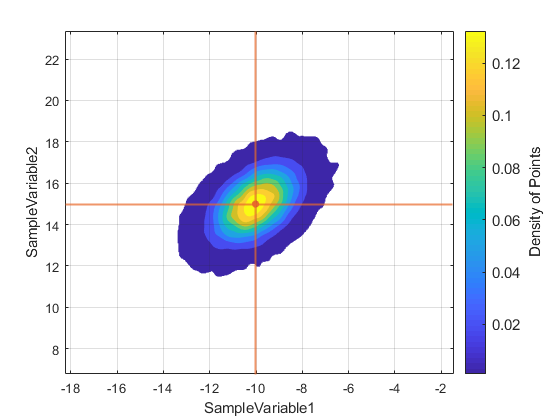

chain.plot.contourf.rows = burnin:chain.count;
chain.plot.contourf.make()
avgx = mean( chain.df.(chain.plot.contourf.xcolumns) );
avgy = mean( chain.df.(chain.plot.contourf.ycolumns) );
chain.plot.lineScatter.target.values = [ avgx, avgy ];
chain.plot.lineScatter.target.make();

## Exporting figures to external files

To extract a figure to an external PNG file, try,

chain.plot.contourf.exportFig("exportedFigure.png","-m4");

The above command will extract the current active figure to an output file with the relatively high resoluton as specified by the flag `-m4`. To make the exported figure smaller, one could specify `-m2` instead. In addition, to generate a figures with background transparency, the flag `-transparent` can be added to the `exportFig` function call,

% chain.plot.contourf.exportFig("exportedFigure.png","-m2 -transparent") % uncomment to export the figure with transparency

**Final Note:**

To see other more sophisticated types of plots that can be automatically made with the ParaMonte visualization tools, visit: [https://www.cdslab.org/paramonte/notes/examples/matlab/mlx/](https://www.cdslab.org/paramonte/notes/examples/matlab/mlx/)